**Introduction**

This document is to explore the waveform of OTFS in ***integer Dopplers*** for ***rectangular pulses***. . Here, we have 4 kinds of testings.

- Case 1: the h[0] starts at the actual beginning of the signal, i.e., 1st CP. $h[0, 1, 2, 3, 4, 5, 6]*s[-2,-1, 0, 1, 2, 3, 4]$

- Case 2: the h[0] starts at the original signal: $h[-2,-1, 0, 1, 2, 3, 4]*s[-2,-1, 0, 1, 2, 3, 4]$

- Case 3: the h[0] starts at the original signal, but the CP part uses the channel on data, i.e., $h[3, 4, 0, 1, 2]*s[3, 4, 0, 1, 2]$

- Case 4: the h[0] starts at the actual beginning of the signal without any CP.$[0, 0, h[0, 1, 2, 3, 4]*s[0, 1, 2, 3, 4]]$

**Basic settings**

clear;
clc;
N = 5;                          % time slot number
M = 4;                         % subcarrier number
% x
x_value = 1+1j;
x_delay_pos = [1, 2, 3, 4];
x_doppl_pos = [2, 2, 2, 2];
x_num = length(x_doppl_pos);
x = zeros(N, M);    
for x_id = 1:x_num
    x(x_doppl_pos(x_id), x_delay_pos(x_id)) = x_value;
end
% channel
hi = 1;
li = 2;
ki = 1;
cp_len = 4

cp_len = 4

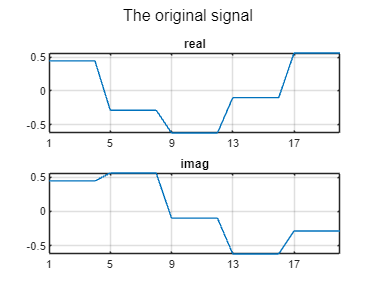

% modulation
s = OTFS_modulation(N,M,x);
plot_s(s, M, N);

% add cp
s_cp = [s(N*M-cp_len+1:N*M);s];

% estimate the outcome
yest = zeros(x_num, 1);
yest_viter = zeros(x_num, 1);
yest_viter_noweight = zeros(x_num, 1);
yesy_viter_noweight_reverse = zeros(x_num, 1);
yest_delay = zeros(x_num, 1);
yest_doppl = zeros(x_num, 1);
for yest_id = 1:x_num
    yest_delay(yest_id) = x_delay_pos(yest_id) + li;
    yest_doppl(yest_id) = x_doppl_pos(yest_id) + ki;
    l = x_delay_pos(yest_id);
    k = x_doppl_pos(yest_id);
    if yest_delay(yest_id) > M
        yest_delay(yest_id) = yest_delay(yest_id) - M;
        l = x_delay_pos(yest_id) - M;
    end
    if yest_doppl(yest_id) > N
        yest_doppl(yest_id) = yest_doppl(yest_id) - N;
        k = k - N;
    end
    yest(yest_id) = exp(2j*pi*(l-1)/M*ki/N)*x_value;
    yest_viter(yest_id) = (N-1)/N*exp(2j*pi*(l-1)/M*ki/N)*exp(-2j*pi*(k-1)/N)*x_value;
    yest_viter_noweight(yest_id) = exp(2j*pi*(l-1)/M*ki/N)*exp(-2j*pi*(k-1)/N)*x_value;
    yesy_viter_noweight_reverse(yest_id) = exp(2j*pi*(l-1)/M*ki/N)*exp(2j*pi*(k-1)/N)*x_value;
end

**Case 1: Our channel 1**

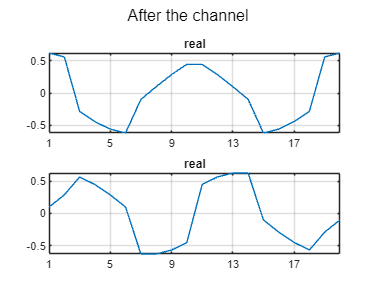

% pass the channel
case1_s_chan = hi*circshift([s_cp.*exp(1j*2*pi/M*(0:M*N+cp_len-1)*ki/N).';zeros(cp_len,1)],li);
case1_r = case1_s_chan(cp_len+1:cp_len+(N*M));
plot_r(case1_r, M, N);

% to Rx DD domain
case1_y = OTFS_demodulation(N,M,case1_r);
% compare
disp("Our channel 1: ")

Our channel 1: 


cur_y = case1_y;
for yest_id = 1:x_num
    fprintf(" - The y at (%d, %d) from (%d, %d): %.4f %+.4fj\n", yest_doppl(yest_id), yest_delay(yest_id), x_doppl_pos(yest_id), x_delay_pos(yest_id), real(cur_y(yest_doppl(yest_id), yest_delay(yest_id))), imag(cur_y(yest_doppl(yest_id), yest_delay(yest_id))));
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest(yest_id)) < 1e-13
        fprintf("   - Normal Est: %.4f %+.4fj\n", real(yest(yest_id)), imag(yest(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest_viter(yest_id)) < 1e-13
        fprintf("   - Cyclic shift Est (no CP): %.4f %+.4fj\n", real(yest_viter(yest_id)), imag(yest_viter(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest_viter_noweight(yest_id)) < 1e-13
        fprintf("   - Cyclic shift Est (CP): %.4f %+.4fj\n", real(yest_viter_noweight(yest_id)), imag(yest_viter_noweight(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yesy_viter_noweight_reverse(yest_id)) < 1e-13
        fprintf("   - Reversed Cyclic shift Est (CP): %.4f %+.4fj\n", real(yesy_viter_noweight_reverse(yest_id)), imag(yesy_viter_noweight_reverse(yest_id)));
    end
end

 - The y at (3, 3) from (2, 1): -0.6420 +1.2601j


   - Reversed Cyclic shift Est (CP): -0.6420 +1.2601j


 - The y at (3, 4) from (2, 2): -1.0000 +1.0000j


   - Reversed Cyclic shift Est (CP): -1.0000 +1.0000j


 - The y at (3, 1) from (2, 3): 1.3968 +0.2212j


   - Normal Est: 1.3968 +0.2212j


 - The y at (3, 2) from (2, 4): 1.2601 +0.6420j


   - Normal Est: 1.2601 +0.6420j


Here, we can see that our channel choise is the reverse of Viterbo's equation in his paper.

**Case 2: Emanuele Viterbo Channel in time domain**

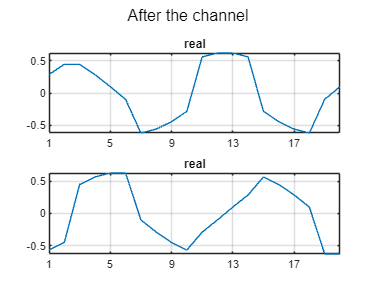

% pass the channel
case2_s_chan_0delay = hi*[s_cp.*exp(1j*2*pi/M*(-cp_len:M*N-1)*ki/N).';zeros(cp_len,1)];
case2_s_chan = hi*circshift([s_cp.*exp(1j*2*pi/M*(-cp_len:M*N-1)*ki/N).';zeros(cp_len,1)],li);
case2_r = case2_s_chan(cp_len+1:cp_len+(N*M));
plot_r(case2_r, M, N);

% to Rx DD domain
case2_y = OTFS_demodulation(N,M,case2_r);
% compare
disp("Emanuele Viterbo channel:")

Emanuele Viterbo channel:


cur_y = case2_y;
for yest_id = 1:x_num
    fprintf(" - The y at (%d, %d) from (%d, %d): %.4f %+.4fj\n", yest_doppl(yest_id), yest_delay(yest_id), x_doppl_pos(yest_id), x_delay_pos(yest_id), real(cur_y(yest_doppl(yest_id), yest_delay(yest_id))), imag(cur_y(yest_doppl(yest_id), yest_delay(yest_id))));
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest(yest_id)) < 1e-13
        fprintf("   - Normal Est: %.4f %+.4fj\n", real(yest(yest_id)), imag(yest(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest_viter(yest_id)) < 1e-13
        fprintf("   - Cyclic shift Est (no CP): %.4f %+.4fj\n", real(yest_viter(yest_id)), imag(yest_viter(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest_viter_noweight(yest_id)) < 1e-13
        fprintf("   - Cyclic shift Est (CP): %.4f %+.4fj\n", real(yest_viter_noweight(yest_id)), imag(yest_viter_noweight(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yesy_viter_noweight_reverse(yest_id)) < 1e-13
        fprintf("   - Reversed Cyclic shift Est (CP): %.4f %+.4fj\n", real(yesy_viter_noweight_reverse(yest_id)), imag(yesy_viter_noweight_reverse(yest_id)));
    end
end

 - The y at (3, 3) from (2, 1): 1.0000 +1.0000j


   - Normal Est: 1.0000 +1.0000j


 - The y at (3, 4) from (2, 2): 0.6420 +1.2601j


   - Normal Est: 0.6420 +1.2601j


 - The y at (3, 1) from (2, 3): 0.6420 -1.2601j


   - Cyclic shift Est (CP): 0.6420 -1.2601j


 - The y at (3, 2) from (2, 4): 1.0000 -1.0000j


   - Cyclic shift Est (CP): 1.0000 -1.0000j


**Case 3: Our Alternative Channel in time domain**

% pass the channel
case3_s_chan = hi*circshift(s.*exp(1j*2*pi/M*(0:M*N-1)*ki/N).',li);
case3_r = case3_s_chan;
plot_r(case3_r, M, N);

% to Rx DD domain
case3_y = OTFS_demodulation(N,M,case3_r);
% compare
disp("Emanuele Viterbo channel:")

Emanuele Viterbo channel:


cur_y = case3_y;
for yest_id = 1:x_num
    fprintf(" - The y at (%d, %d) from (%d, %d): %.4f %+.4fj\n", yest_doppl(yest_id), yest_delay(yest_id), x_doppl_pos(yest_id), x_delay_pos(yest_id), real(cur_y(yest_doppl(yest_id), yest_delay(yest_id))), imag(cur_y(yest_doppl(yest_id), yest_delay(yest_id))));
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest(yest_id)) < 1e-13
        fprintf("   - Normal Est: %.4f %+.4fj\n", real(yest(yest_id)), imag(yest(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest_viter(yest_id)) < 1e-13
        fprintf("   - Cyclic shift Est (no CP): %.4f %+.4fj\n", real(yest_viter(yest_id)), imag(yest_viter(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest_viter_noweight(yest_id)) < 1e-13
        fprintf("   - Cyclic shift Est (CP): %.4f %+.4fj\n", real(yest_viter_noweight(yest_id)), imag(yest_viter_noweight(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yesy_viter_noweight_reverse(yest_id)) < 1e-13
        fprintf("   - Reversed Cyclic shift Est (CP): %.4f %+.4fj\n", real(yesy_viter_noweight_reverse(yest_id)), imag(yesy_viter_noweight_reverse(yest_id)));
    end
end

 - The y at (3, 3) from (2, 1): 1.0000 +1.0000j


   - Normal Est: 1.0000 +1.0000j


 - The y at (3, 4) from (2, 2): 0.6420 +1.2601j


   - Normal Est: 0.6420 +1.2601j


 - The y at (3, 1) from (2, 3): 0.6420 -1.2601j


   - Cyclic shift Est (CP): 0.6420 -1.2601j


 - The y at (3, 2) from (2, 4): 1.0000 -1.0000j


   - Cyclic shift Est (CP): 1.0000 -1.0000j


**Case 4: No CP using our channel**

In this case, our channel model is the same as Emanuele's.

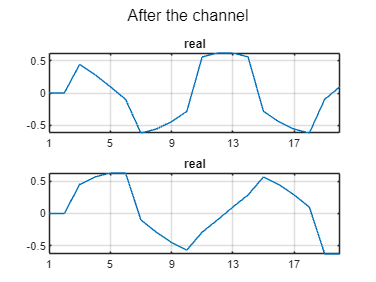

% pass the channel
case4_s_chan = hi*circshift([s.*exp(1j*2*pi/M*(0:M*N-1)*ki/N).';zeros(cp_len,1)],li);
case4_r = case4_s_chan(1:M*N);
plot_r(case4_r, M, N);

% to Rx DD domain
case4_y = OTFS_demodulation(N,M,case4_r);
% compare
disp("No CP using our channel 1:")

No CP using our channel 1:


cur_y = case4_y;
for yest_id = 1:x_num
    fprintf(" - The y at (%d, %d) from (%d, %d): %.4f %+.4fj\n", yest_doppl(yest_id), yest_delay(yest_id), x_doppl_pos(yest_id), x_delay_pos(yest_id), real(cur_y(yest_doppl(yest_id), yest_delay(yest_id))), imag(cur_y(yest_doppl(yest_id), yest_delay(yest_id))));
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest(yest_id)) < 1e-13
        fprintf("   - Normal Est: %.4f %+.4fj\n", real(yest(yest_id)), imag(yest(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest_viter(yest_id)) < 1e-13
        fprintf("   - Cyclic shift Est (no CP): %.4f %+.4fj\n", real(yest_viter(yest_id)), imag(yest_viter(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yest_viter_noweight(yest_id)) < 1e-13
        fprintf("   - Cyclic shift Est (CP): %.4f %+.4fj\n", real(yest_viter_noweight(yest_id)), imag(yest_viter_noweight(yest_id)));
    end
    if abs(cur_y(yest_doppl(yest_id), yest_delay(yest_id)) - yesy_viter_noweight_reverse(yest_id)) < 1e-13
        fprintf("   - Reversed Cyclic shift Est (CP): %.4f %+.4fj\n", real(yesy_viter_noweight_reverse(yest_id)), imag(yesy_viter_noweight_reverse(yest_id)));
    end
end

 - The y at (3, 3) from (2, 1): 1.0000 +1.0000j


   - Normal Est: 1.0000 +1.0000j


 - The y at (3, 4) from (2, 2): 0.6420 +1.2601j


   - Normal Est: 0.6420 +1.2601j


 - The y at (3, 1) from (2, 3): 0.5136 -1.0081j


   - Cyclic shift Est (no CP): 0.5136 -1.0081j


 - The y at (3, 2) from (2, 4): 0.8000 -0.8000j


   - Cyclic shift Est (no CP): 0.8000 -0.8000j


**Functions**

function plot_s(s, M, N)
    figure("name", "The original signal")
    subplot(2,1,1)
    plot(real(s));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(s));
    title("imag");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("The original signal")
end
function plot_r(r, M, N)
    figure("name", "Time domain")
    subplot(2,1,1)
    plot(real(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("After the channel")
end